# Actividad 6: Robot péndulo (1gdl)

**Paola Rojas Domínguez A01737136**

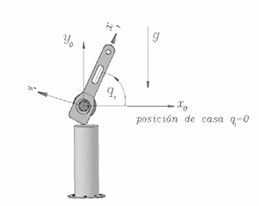

## Inicialización y Declaración de Variables

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores. Posteriormente, se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t)  t  %Angulos de cada articulación
syms m1 Ixx1 Iyy1 Izz1  %Masas y matrices de Inercia
syms l1 lc1   %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

Creamos el vector de coordenadas generalizadas

Q= [th1];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
th1(t)



Creamos el vector de velocidades generalizadas, la velocidad general es la derivada temporal de las coordenadas generalizadas.

Qp= diff(Q, t);
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
 d
-- th1(t)
dt



 Creamos el vector de aceleraciones articulares, la aceleración general es la derivada temporal de las velocidades generalizadas.

Qpp= diff(Qp, t);
disp('Aceleraciones generalizadas'); pretty (Qpp);

Aceleraciones generalizadas
  2
 d
--- th1(t)
  2
dt



Se configura el robot con una articulacion rotacional, representando su tipo con un vector donde 0 es rotacional y 1 prismático

RP=[0];

Posteriormente, definimos los grados de libertad (GDL), es decir, el número de parámetros independientes que definen la posición del extremo del robot.

GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares. Para ello, se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

### Articulación 1

%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

Las matrices de transformación homogénea, combinan la rotación y traslación en un solo modelo matemático. Se construyen las matrices locales y globales de transformación para obtener la posición y orientación del extremo del robot en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

El bucle `for` recorre cada articulación del robot para calcular sus matrices de transformación homogénea locales y globales. Primero, genera la matriz de transformación local, que describe la posición y orientación de la articulación en relación con la anterior. Luego, obtiene la matriz de transformación global, que representa la posición y orientación en el sistema de referencia inercial, acumulando las transformaciones previas. Finalmente, extrae la matriz de rotación y el vector de posición, fundamentales para la cinemática directa y el cálculo del Jacobiano.

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1
/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



### Cálculo del jacobiano lineal y angular de forma analítica

El jacobiano analítico es calculado mediante productos vectoriales, considerando el tipo de articulación

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
    elseif RP(k)==1 
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
\        0        /



disp('Jacobiano ángular obtenido de forma analítica'); pretty (Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0 \
|   |
| 0 |
|   |
\ 1 /



%Matriz de Jacobiano Completa
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
disp('Matriz de Jacobiano'); pretty(Jacobiano);

Matriz de Jacobiano
/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
|        0        |
|                 |
|        0        |
|                 |
|        0        |
|                 |
\        1        /



### Velocidades Lineales y Angulares

Finalmente, se obtienen las velocidades multiplicando los jacobianos por el vector de velocidades articulares

La velocidad lineal describe el desplazamiento del efector.

V=simplify (Jv_a*Qp);
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/                  d        \
| -l1 sin(th1(t)) -- th1(t) |
|                 dt        |
|                           |
|                  d        |
|  l1 cos(th1(t)) -- th1(t) |
|                 dt        |
|                           |
\             0             /



Mientras que la velocidad angular describe la rotación del efector.

W=simplify (Jw_a*Qp);
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/     0     \
|           |
|     0     |
|           |
|  d        |
| -- th1(t) |
\ dt        /



## Energía Cinética

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1)/2, l1, lc1);%La función subs sustituye l1 por lc1 en 
                                %la expresión P(:,:,1)/2

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];


%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos la velocidad angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

### Eslabón 1

V1_Total= V+cross(W,P01); %Se suma la velocidad lineal producida por la velocidad angular producida en el punto P01             
K1= (1/2*m1*(V1_Total))'*(V1_Total) + (1/2*W)'*(I1*W);
K1= simplify (K1);
disp('Energía Cinética en el Eslabón 1'); pretty (K1);

Energía Cinética en el Eslabón 1
      |  d        | 2    |  d        | 2     ______           __          2             2
Izz1  | -- th1(t) |      | -- th1(t) |   cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (lc1 + 2 l1)
      | dt        |      | dt        |
--------------------- + -------------------------------------------------------------------------------
          2                                                 8 l1 lc1



### Energía cinética total

K_Total= simplify (K1);
disp('Energía Cinética Total'); pretty (K_Total);

Energía Cinética Total
      |  d        | 2    |  d        | 2     ______           __          2             2
Izz1  | -- th1(t) |      | -- th1(t) |   cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (lc1 + 2 l1)
      | dt        |      | dt        |
--------------------- + -------------------------------------------------------------------------------
          2                                                 8 l1 lc1



## Energía Potencial

%Obtenemos las alturas respecto a la gravedad
h1= P01(2); %Tomo la altura paralela al eje z

U1=m1*g*h1;

%Calculamos la energía potencial total
U_Total= U1;
disp('Energía Potencial Total'); pretty(U_Total);

Energía Potencial Total
g lc1 m1 sin(th1(t))
--------------------
          2



## Modelo de energía

%Obtenemos el Lagrangiano
Lagrangiano= simplify (K_Total - U_Total);
disp('Lagrangiano'); pretty (Lagrangiano);

Lagrangiano
      |  d        | 2                           |  d        | 2     ______           __          2             2
Izz1  | -- th1(t) |                             | -- th1(t) |   cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (lc1 + 2 l1)
      | dt        |     g lc1 m1 sin(th1(t))    | dt        |
--------------------- - -------------------- + -------------------------------------------------------------------------------
          2                       2                                                8 l1 lc1



%Modelo de Energía
H= simplify (K_Total + U_Total);
disp('Modelo de energía'); pretty (H)

Modelo de energía
      |  d        | 2                           |  d        | 2     ______           __          2             2
Izz1  | -- th1(t) |                             | -- th1(t) |   cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (lc1 + 2 l1)
      | dt        |     g lc1 m1 sin(th1(t))    | dt        |
--------------------- + -------------------- + -------------------------------------------------------------------------------
          2                       2                                                8 l1 lc1



toc

Elapsed time is 3.788787 seconds.
